# mainFSL (R&S FSL-6)

Trata-se da função principal que possibilita conexão aos dispositivos indicados a seguir, escrevendo um arquivo no formato **RFlook Bin v.1** para cada uma das faixas a monitorar.

- **Analisador de espectro fabricado pela R&S, modelo FSL-6**;

- GPS fabricado pela Garmin ou embarcado em *smartphone.*

Na imagem apresentada a seguir é possível visualizar sob a forma de diagrama os arquivos atualmente presentes no projeto.

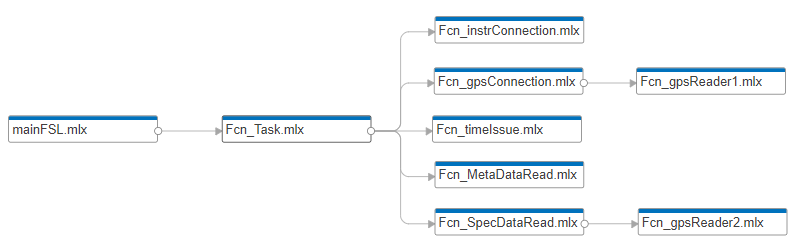

Descrição resumida de cada uma das funções:

- **mainFSL**: criar o *timer* que disparará o início da tarefa de monitoração.

- **Fcn_Task**: controla todas as operações de conexão ao(s) instrumento(s) e escrita/leitura do(s) arquivo(s) binário(s), acionando as funções Fcn_instrConnection, Fcn_gpsConnectcion, Fcn_timeIssue, Fcn_MetaDataRead e Fcn_SpecDataRead, nessa ordem.

- **Fcn_instrConnection**: Possibilita conexão a um analisador de espectro (ou receptor) por meio de uma comunicação TCP/IP SOCKET, quando devem ser indicados o endereço IP e a porta, ou usando o padrão da indústria VISA, que apresenta uma comunicação mais estável.

- **Fcn_gpsConnection**: Possibilita conexão a um dispositivo GPS por meio de uma porta de comunicação (inclusive "virtual", caso se trate de um GPS fabricado pela Garmin que esteja conectado à porta USB do computador) ou de uma comunicação TCP/IP, quando devem ser indicados o endereço IP e a porta.

- **Fcn_issueTime**: Afere o fator de revisita para cada uma das faixas a monitorar, estimando o número de amostras que constarão no(s) arquivo(s) binário(s).

- **Fcn_MetaDataRead**: Configura no analisador de espectro (ou receptor), para cada uma das faixas a monitorar, os parâmetros indicados no "*script appColeta*" - TraceMode, Detector, LevelUnit, F0, F1, Resolution e DataPoints. Posteriormente à tentativa de configuração dos supracitados parâmetros, a função requisita os valores atuais de alguns dos parâmetros que irão compor o cabeçalho do(s) arquivo(s) binário(s).

- **Fcn_SpecDataRead**: Coleta informações do analisador de espectro e do GPS, escrevendo no(s) arquivo(s) binário(s).

Versão: **06/04/2021**.

function mainFSL(Task, Connection, UserFolder)

    arguments
        Task       struct
        Connection struct = struct('Instrument',    struct('Type', 'TCPIP', 'IP', '10.71.10.2', 'Port', 5025), ...
                                   'gpsInstrument', struct('Type', 'COM', 'Port', 'COM1'))
        UserFolder char   = 'C:\Users\Administrador\OneDrive - ANATEL\appColeta\Temp'
    end
    
    t0 = datetime('now');
    
    t1 = Task.startTime;
    t2 = t1 + Task.Duration;
    
    if t0 < t1    ; waitTime = seconds(t1-t0);
    elseif t0 < t2; waitTime = 0;
    else          ; error('Favor ajustar período de início ou duração da monitoração.')
    end
    
%     Fcn_Task(Task, Connection, UserFolder)
    
    tmr = timer('ExecutionMode', 'singleShot', ...
                'BusyMode',      'queue',      ...
                'StartDelay',    waitTime-3,   ...
                'TimerFcn',      @(~,~)Fcn_Task(Task, Connection, UserFolder));
    
    start(tmr)
    
end